# Plotting Data from Tables 

## Kristen Fogaren     1/30/22

### This live script walks the user through making plots from data stored in tables in Matlab using data collected with Aquatrolls at SMIIL.

### Setting up the workspace:

Download data file 'OpenWaterPlatforms.mat' from [https://drive.google.com/file/d/1mbK1pmsxvSJeJIO6EDn_59z0TdRcTrzP/view?usp=sharing](https://drive.google.com/file/d/1mbK1pmsxvSJeJIO6EDn_59z0TdRcTrzP/view?usp=sharing)

Navigate to where file is located on local computer and load file into matlab workspace. 

 cd('C:\Users\joann\Documents\BIOGEOCHEM MATLAB WORK') % Location will change for each person (cd = current directory)
 load OpenWaterPlatforms.mat % loads in matlab file
 
 whos % Lists variables in workspace 

  Name           Size              Bytes  Class                        Attributes

  ans            8x15               5143  table                                  
  ax1            1x1                   8  matlab.graphics.axis.Axes              
  ax2            1x1                   8  matlab.graphics.axis.Axes              
  ax3            1x1                   8  matlab.graphics.axis.Axes              
  ax4            1x1                   8  matlab.graphics.axis.Axes              
  ax5            1x1                   8  matlab.graphics.axis.Axes              
  ax6            1x1                   8  matlab.graphics.axis.Axes              
  f              1x1                   8  matlab.ui.Figure                       
  gull       31423x15            3774943  table                                  
  north      29596x15            3555703  table                                  
  south      34061x15            4091503  table                                  



We have three tables named gull, north, and south that have 15 columns. To see what the column headers are use head(tablename).

head(gull) % returns first 8 lines of table and the column headers

ans = 8×15 table
           dt_UTC           Depth1_m    Temp1_C    Salinity1_psu    Turbidity_ntu     pH     DO1_Conc_mgL    Depth2_m    Temp2_C    Salinity2_psu    Chl_a_RFU    Nitrate_mgL    DO2_Conc_mgL           dt_LOC               dn    
    ____________________    ________    _______    _____________    _____________    ____    ____________    ________    _______    _____________    _________    ___________    ____________    ____________________    __________

    30-Jun-2021 

### Variables: 

- dt_UTC = datetime (Timezone is UTC)

- Depth1_m = sensor depth for first sonde (m)

- Temp1_C = temperature for first sonde (C)

- Salinity1_psu = salinity for first sonde (PSU); PSU = practical salinity units 

- Turbidity1_ntu = turbidity for first sonde (NTU); NTU = Nephelometric turbidity units 

- pH = pH (-) ; - = unitless

- DO1_Conc_mgL = dissolved oxygen concentration for first sonde (mg/L)

- Depth2_m = sensor depth for second sonde (m)

- Temp2_C = temperature for second sonde (C)

- Salinity2_psu = salinity for second sonde (PSU) 

- Chl_a_RFU = chloropyll-a (RFU) 

- Nitrate_mgL = nitrate concentration (mg/L)

- DO2_Conc_mgL = dissolved oxygen concentration for second sonde (mg/L)

- dt_LOC = datetime (Timezone is Local, ET)

- dn_LOC = date number, Matlab time (Timezone is Local, ET)

### Plotting:

To access data in tables use dot syntax. (aka tablename.columnname)

#### If you want to plot temperature for the first sonde at gull:

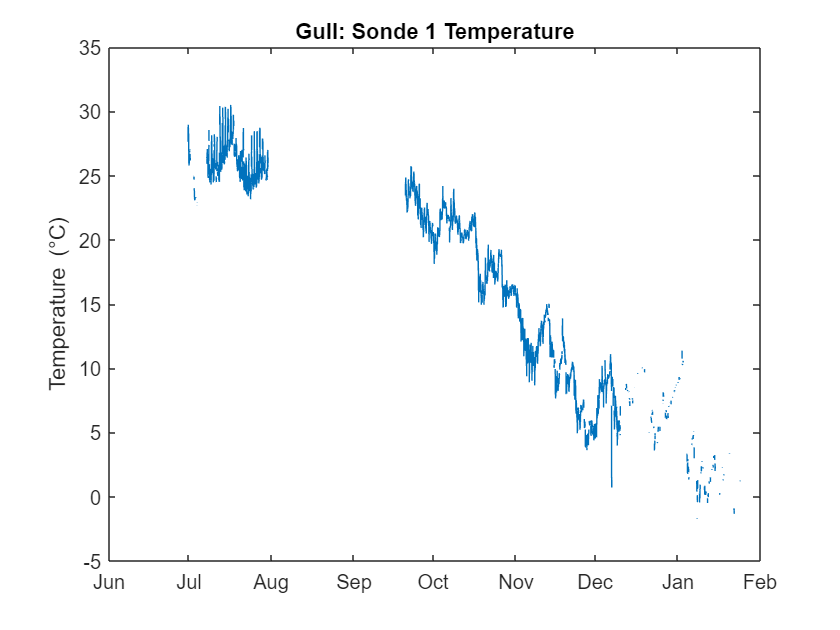

figure % opens figure
plot(gull.dn,gull.Temp1_C) % Plots a line temp1 for local time
ylabel('Temperature (\circC)') % Adds y label with degree symbol
title('Gull: Sonde 1 Temperature') % Adds title to figure 
datetick % Changes Matlab time format to common time

#### What if you want to compare to sonde 2 at gull? 

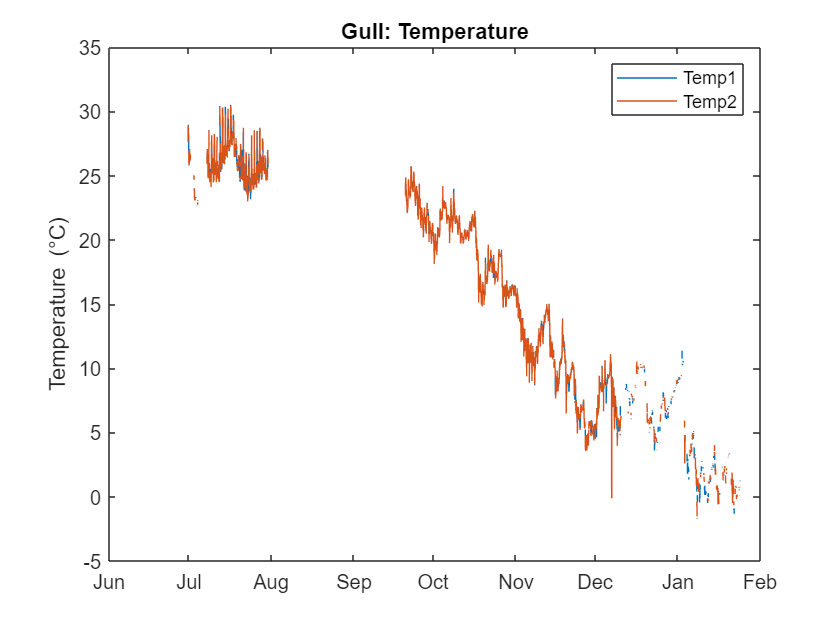

figure 
plot(gull.dn,gull.Temp1_C) 
hold on % If don't use then second plot command will overwrite first plot command
plot(gull.dn,gull.Temp2_C) % Adds a line for temp 2 to the figure
ylabel('Temperature (\circC)') 
title('Gull: Temperature') % Update title 
legend('Temp1','Temp2') % Adds legend to figure, needs to be in order they are plotted 
datetick 

#### What if you want to zoom in on a particular time period? 

You can use the zoom feature on the top right of the figure or you can code the dates by adding time limits to the x axis if you know the time period of interest. 

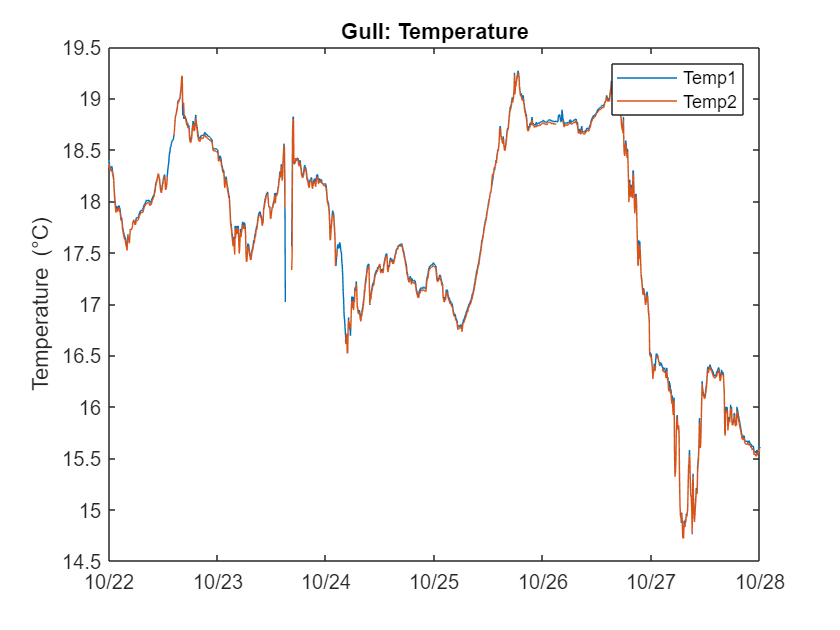

figure 
plot(gull.dn,gull.Temp1_C) 
hold on 
plot(gull.dn,gull.Temp2_C) 
ylabel('Temperature (\circC)') 
title('Gull: Temperature') 
legend('Temp1','Temp2') 
xlim([datenum(2021,10,22,00,00,00) datenum(2021,10,28,00,00,00)]) % Limits for x axis in matlab time format
datetick('x','Keeplimits') % Keeplimits so that doesn't revert back to original timespan of plot (Jun - Feb)

#### Now let's make it pretty :) 

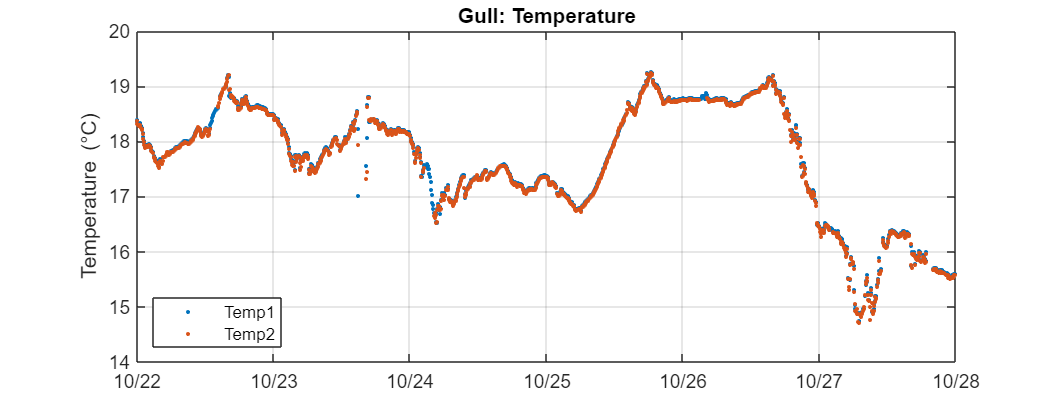

f = figure('DefaultAxesFontSize',10); % open figure and sets font size
f.Position = [0 0 1040 400]; % Set size of figure in pixels [start_from_left start_from_bottom width height]
plot(gull.dn,gull.Temp1_C,'.') % Changes line to a dot for each data point
hold on 
plot(gull.dn,gull.Temp2_C,'.') % Changes line to a dot for each data point
ylabel('Temperature (\circC)') 
title('Gull: Temperature') 
legend('Temp1','Temp2','Location','SW') % Change location of legend so data isn't hidden 
xlim([datenum(2021,10,22,00,00,00) datenum(2021,10,28,00,00,00)])
datetick('x','Keeplimits') 
grid on

#### Now let's compare it to the other platforms:

- Add them all to one plot

- Create sub plots for each open-water platform

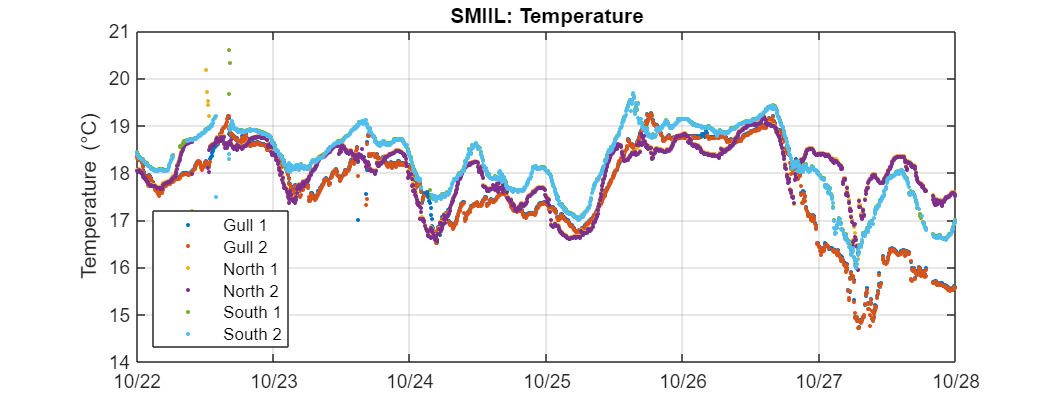

% #1 
f = figure('DefaultAxesFontSize',10); 
f.Position = [0 0 1040 400]; 
plot(gull.dn,gull.Temp1_C,'.') 
hold on % 
plot(gull.dn,gull.Temp2_C,'.') 
plot(north.dn,north.Temp1_C,'.') % Adds north data 
plot(north.dn,north.Temp2_C,'.')
plot(south.dn,south.Temp1_C,'.') % Adds south data 
plot(south.dn,south.Temp2_C,'.')
ylabel('Temperature (\circC)') 
title('SMIIL: Temperature') % Updated  
legend('Gull 1','Gull 2','North 1','North 2','South 1','South 2','Location','SW') % Add all data legends in order they are plotted  
xlim([datenum(2021,10,22,00,00,00) datenum(2021,10,28,00,00,00)])
datetick('x','Keeplimits') 
grid on

#### Looks pretty busy, let's try subplots: 

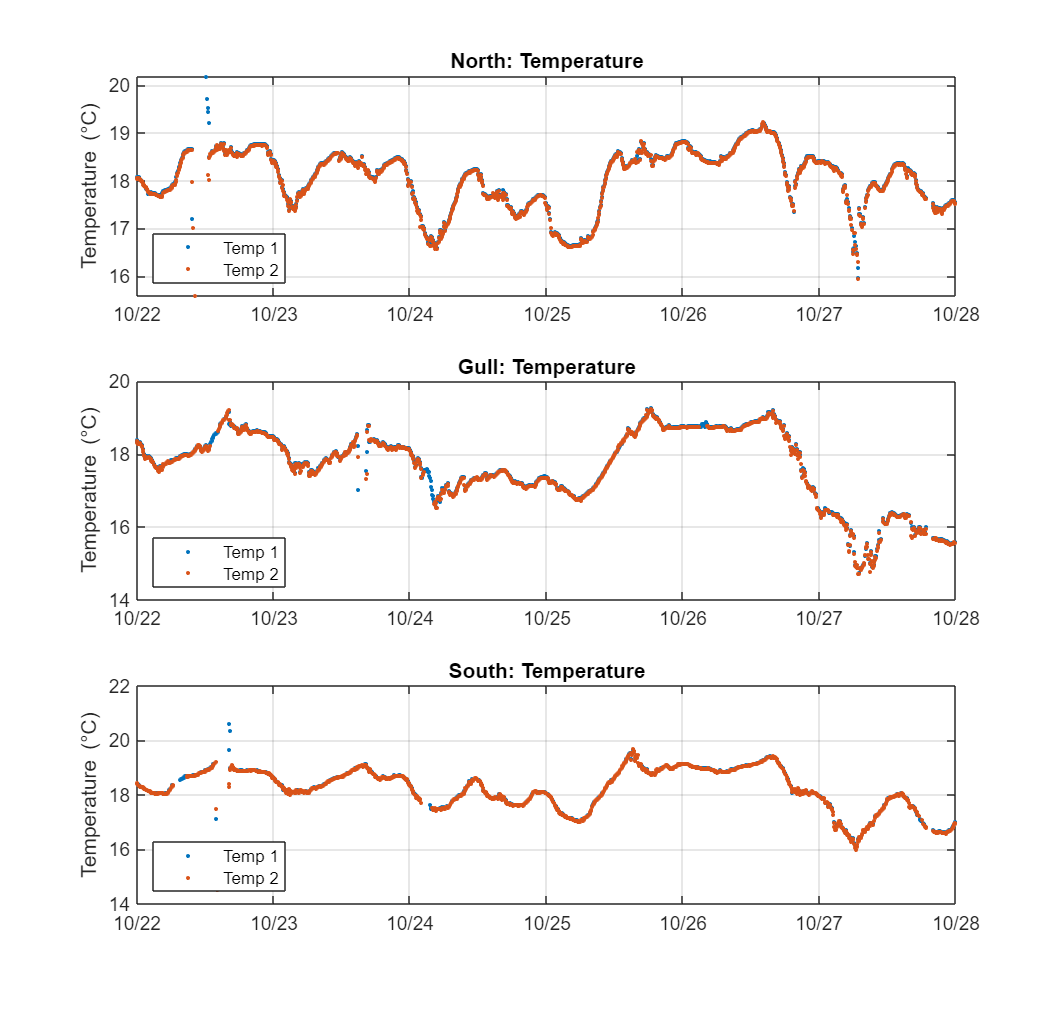

% #2 
f = figure('DefaultAxesFontSize',10); 
f.Position = [0 0 1040 1000]; % Change to make figure taller for more plots

subplot(3,1,1) % Breaks figure into plots (3 rows, 1 column, 1st plot)
plot(north.dn,north.Temp1_C,'.') 
hold on
plot(north.dn,north.Temp2_C,'.')
ylabel('Temperature (\circC)') 
title('North: Temperature') % Updated  
legend('Temp 1','Temp 2','Location','SW') % Update for each subplot 
xlim([datenum(2021,10,22,00,00,00) datenum(2021,10,28,00,00,00)])
datetick('x','Keeplimits') 
grid on

subplot(3,1,2) % Breaks figure into plots (3 rows, 1 column, 2nd plot)
plot(gull.dn,gull.Temp1_C,'.') 
hold on % Need a hold on for each plot or second plot command will overwrite first 
plot(gull.dn,gull.Temp2_C,'.') 
ylabel('Temperature (\circC)') 
title('Gull: Temperature') % Updated  
legend('Temp 1','Temp 2','Location','SW') % Update for each subplot 
xlim([datenum(2021,10,22,00,00,00) datenum(2021,10,28,00,00,00)])
datetick('x','Keeplimits') 
grid on

subplot(3,1,3) % Breaks figure into plots (3 rows, 1 column, 3rd plot)
plot(south.dn,south.Temp1_C,'.')
hold on % Need a hold on for each plot or second plot command will overwrite first 
plot(south.dn,south.Temp2_C,'.')
ylabel('Temperature (\circC)') 
title('South: Temperature') % Updated  
legend('Temp 1','Temp 2','Location','SW') % Update for each subplot 
xlim([datenum(2021,10,22,00,00,00) datenum(2021,10,28,00,00,00)])
datetick('x','Keeplimits') 
grid on

#### Looks a lot better, but to be able to compare easily let's make the y-axis limits the same (14 - 20) in all three plots

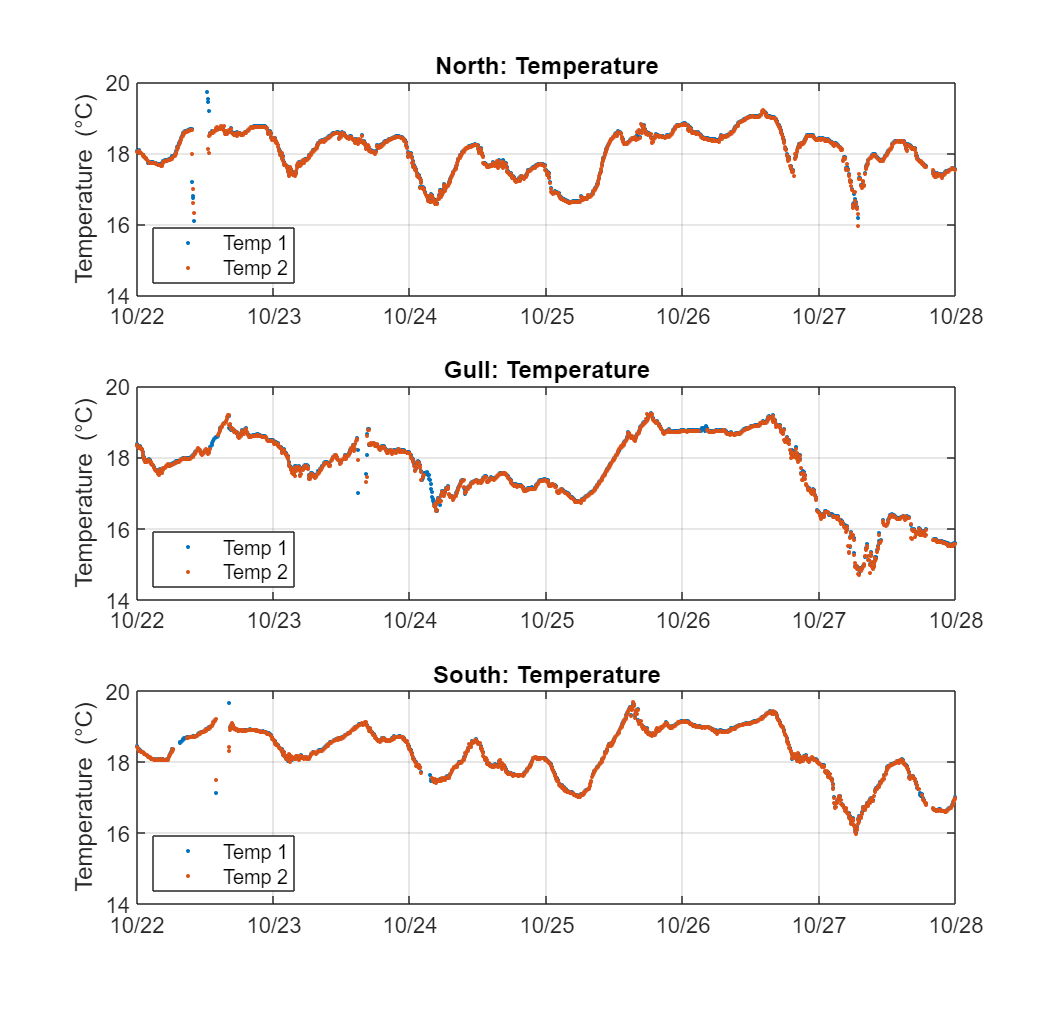

% #2 
f = figure('DefaultAxesFontSize',12);
f.Position = [0 0 1040 1000]; 

subplot(3,1,1) 
plot(north.dn,north.Temp1_C,'.') 
hold on
plot(north.dn,north.Temp2_C,'.')
ylabel('Temperature (\circC)') 
title('North: Temperature') 
legend('Temp 1','Temp 2','Location','SW')  
xlim([datenum(2021,10,22,00,00,00) datenum(2021,10,28,00,00,00)])
ylim([14 20]) % sets y limit, lower limit then upper limit 
datetick('x','Keeplimits') 
grid on

subplot(3,1,2) 
plot(gull.dn,gull.Temp1_C,'.') 
hold on 
plot(gull.dn,gull.Temp2_C,'.') 
ylabel('Temperature (\circC)') 
title('Gull: Temperature') 
legend('Temp 1','Temp 2','Location','SW') 
xlim([datenum(2021,10,22,00,00,00) datenum(2021,10,28,00,00,00)])
ylim([14 20]) % sets y limit, lower limit then upper limit 
datetick('x','Keeplimits') 
grid on

subplot(3,1,3) 
plot(south.dn,south.Temp1_C,'.')
hold on 
plot(south.dn,south.Temp2_C,'.')
ylabel('Temperature (\circC)') 
title('South: Temperature') 
legend('Temp 1','Temp 2','Location','SW') 
xlim([datenum(2021,10,22,00,00,00) datenum(2021,10,28,00,00,00)])
ylim([14 20]) % sets y limit, lower limit then upper limit 
datetick('x','Keeplimits') 
grid on

#### Can you make a plot with a fourth panel that has our temp data from the Pond YSI? 

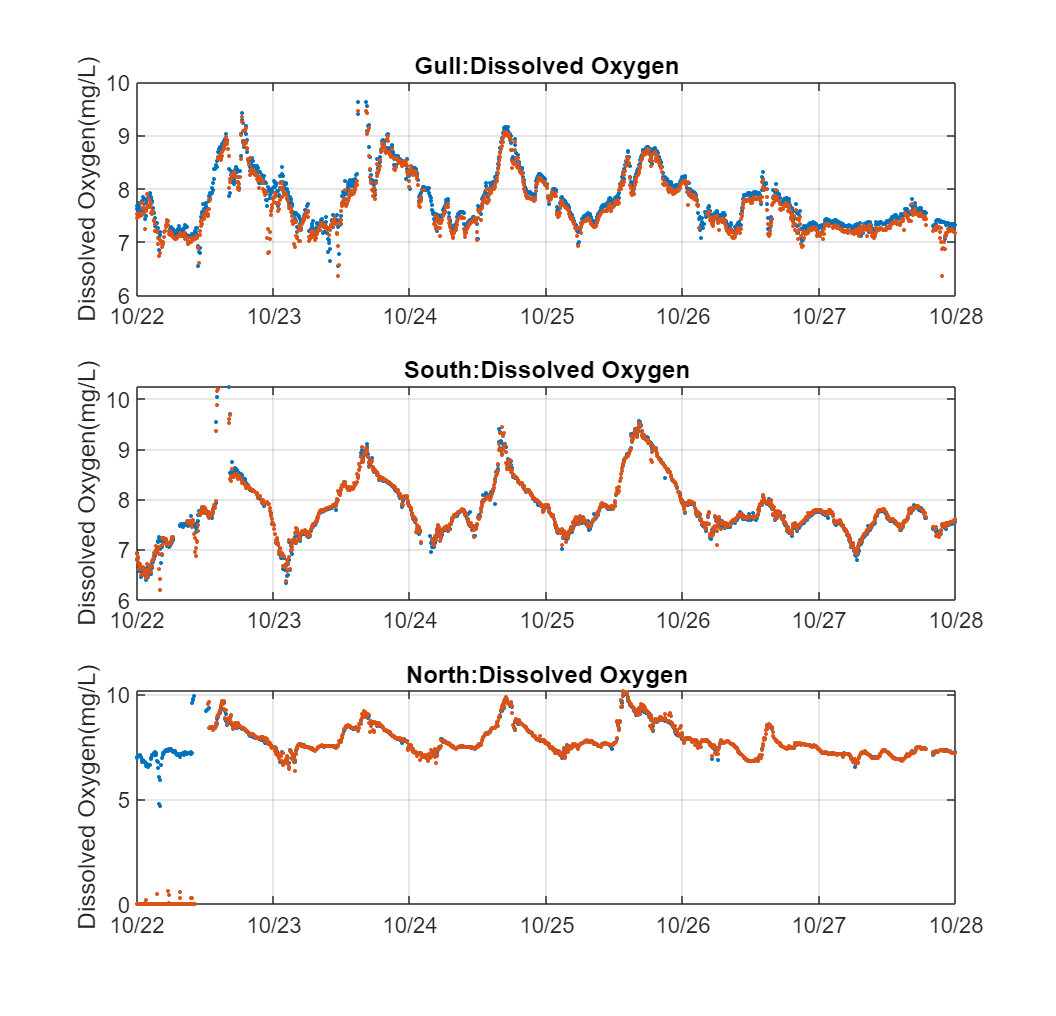

f = figure('DefaultAxesFontSize',12);
f.Position = [0 0 1040 1000]; 

subplot(3,1,1)
plot(gull.dn,gull.DO1_Conc_mgL,'.')
hold on
plot(gull.dn,gull.DO2_Conc_mgL,'.')
ylabel('Dissolved Oxygen(mg/L)')
title('Gull:Dissolved Oxygen')
xlim([datenum(2021,10,22,00,00,00) datenum(2021,10,28,00,00,00)])
datetick('x','Keeplimits')
grid on

subplot(3,1,2)
plot(south.dn,south.DO1_Conc_mgL,'.')
hold on
plot(south.dn, south.DO2_Conc_mgL,'.')
ylabel('Dissolved Oxygen(mg/L)')
title('South:Dissolved Oxygen')
xlim([datenum(2021,10,22,00,00,00) datenum(2021,10,28,00,00,00)])
datetick('x','Keeplimits')
grid on

subplot(3,1,3)
plot(north.dn,north.DO1_Conc_mgL,'.')
hold on
plot(north.dn, north.DO2_Conc_mgL,'.')
ylabel('Dissolved Oxygen(mg/L)')
title('North:Dissolved Oxygen')
xlim([datenum(2021,10,22,00,00,00) datenum(2021,10,28,00,00,00)])
datetick('x','Keeplimits')
grid on

Plots for Dissolved Oxygen and pH

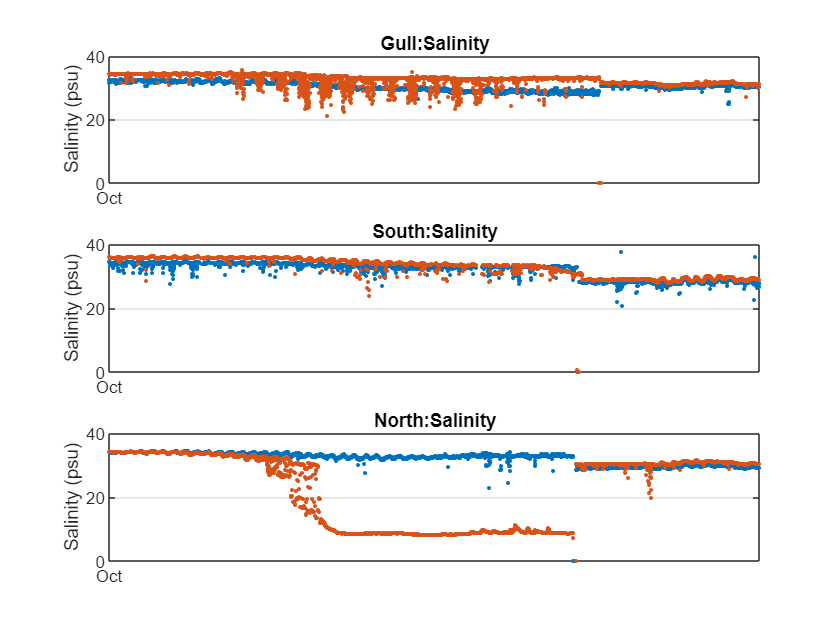

figure
subplot(3,1,1)
plot(gull.dn,gull.Salinity1_psu,'.')
hold on
plot(gull.dn, gull.Salinity2_psu,'.')
ylabel('Salinity (psu)')
title('Gull:Salinity')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

subplot(3,1,2)
plot(south.dn,south.Salinity1_psu,'.')
hold on
plot(south.dn, south.Salinity2_psu,'.')
ylabel('Salinity (psu)')
title('South:Salinity')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

subplot(3,1,3)
plot(north.dn,north.Salinity1_psu,'.')
hold on
plot(north.dn, north.Salinity2_psu,'.')
ylabel('Salinity (psu)')
title('North:Salinity')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

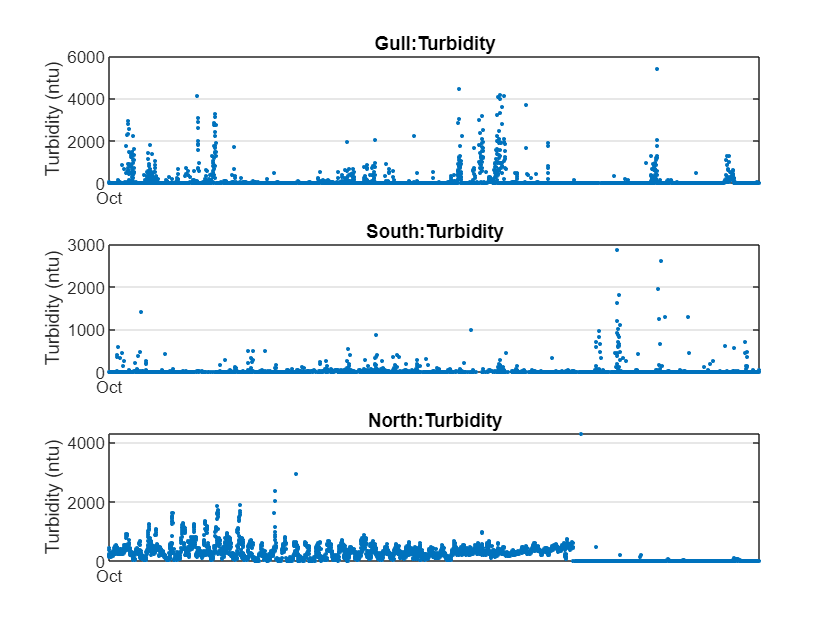

figure
subplot(3,1,1)
plot(gull.dn,gull.Turbidity_ntu,'.')
ylabel('Turbidity (ntu)')
title('Gull:Turbidity')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

subplot(3,1,2)
plot(south.dn,south.Turbidity_ntu,'.')
ylabel('Turbidity (ntu)')
title('South:Turbidity')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

subplot(3,1,3)
plot(north.dn,north.Turbidity_ntu,'.')
ylabel('Turbidity (ntu)')
title('North:Turbidity')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

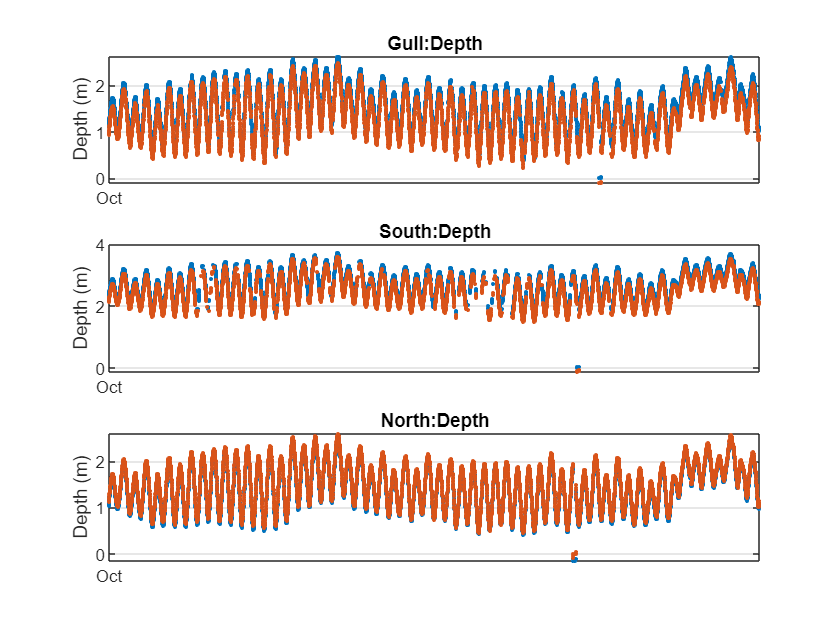

figure
subplot(3,1,1)
plot(gull.dn,gull.Depth1_m,'.')
hold on
plot(gull.dn, gull.Depth2_m,'.')
ylabel('Depth (m)')
title('Gull:Depth')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

subplot(3,1,2)
plot(south.dn,south.Depth1_m,'.')
hold on
plot(south.dn, south.Depth2_m,'.')
ylabel('Depth (m)')
title('South:Depth')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

subplot(3,1,3)
plot(north.dn,north.Depth1_m,'.')
hold on
plot(north.dn, north.Depth2_m,'.')
ylabel('Depth (m)')
title('North:Depth')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

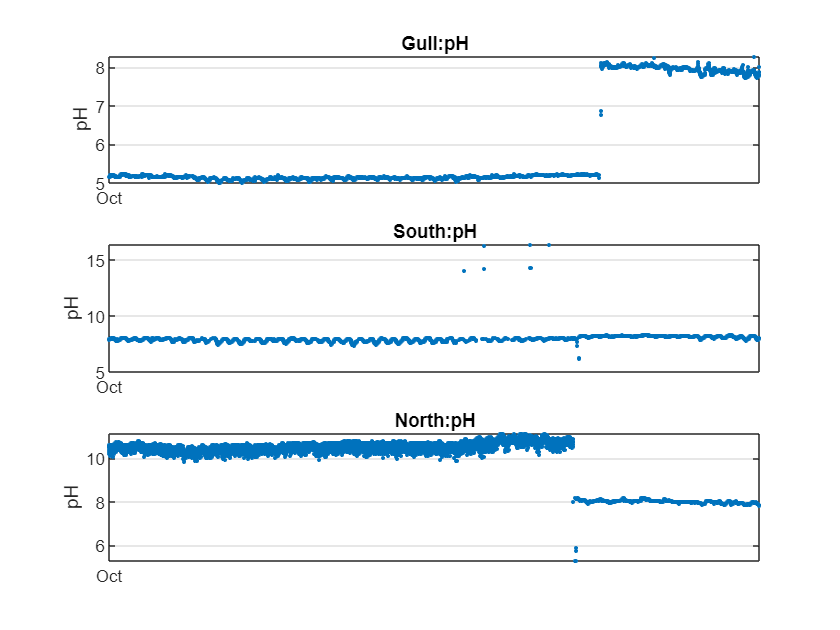

figure
subplot(3,1,1)
plot(gull.dn,gull.pH,'.')
ylabel('pH')
title('Gull:pH')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

subplot(3,1,2)
plot(south.dn,south.pH,'.')
ylabel('pH')
title('South:pH')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

subplot(3,1,3)
plot(north.dn,north.pH,'.')
ylabel('pH')
title('North:pH')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

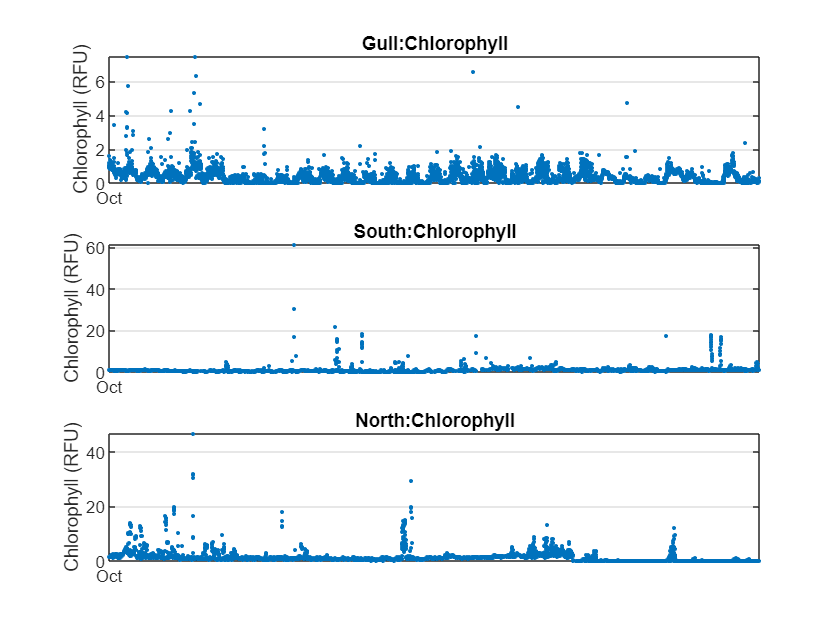

figure
subplot(3,1,1)
plot(gull.dn,gull.Chl_a_RFU,'.')
ylabel('Chlorophyll (RFU)')
title('Gull:Chlorophyll')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

subplot(3,1,2)
plot(south.dn,south.Chl_a_RFU,'.')
ylabel('Chlorophyll (RFU)')
title('South:Chlorophyll')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

subplot(3,1,3)
plot(north.dn,north.Chl_a_RFU,'.')
ylabel('Chlorophyll (RFU)')
title('North:Chlorophyll')
xlim([datenum(2021,10,1,00,00,00) datenum(2021,10,31,00,00,00)])
datetick('x','Keeplimits')
grid on

Scale of chlorophyll for the Gull platform is much lower than those of North and South. Not entirely sure why?

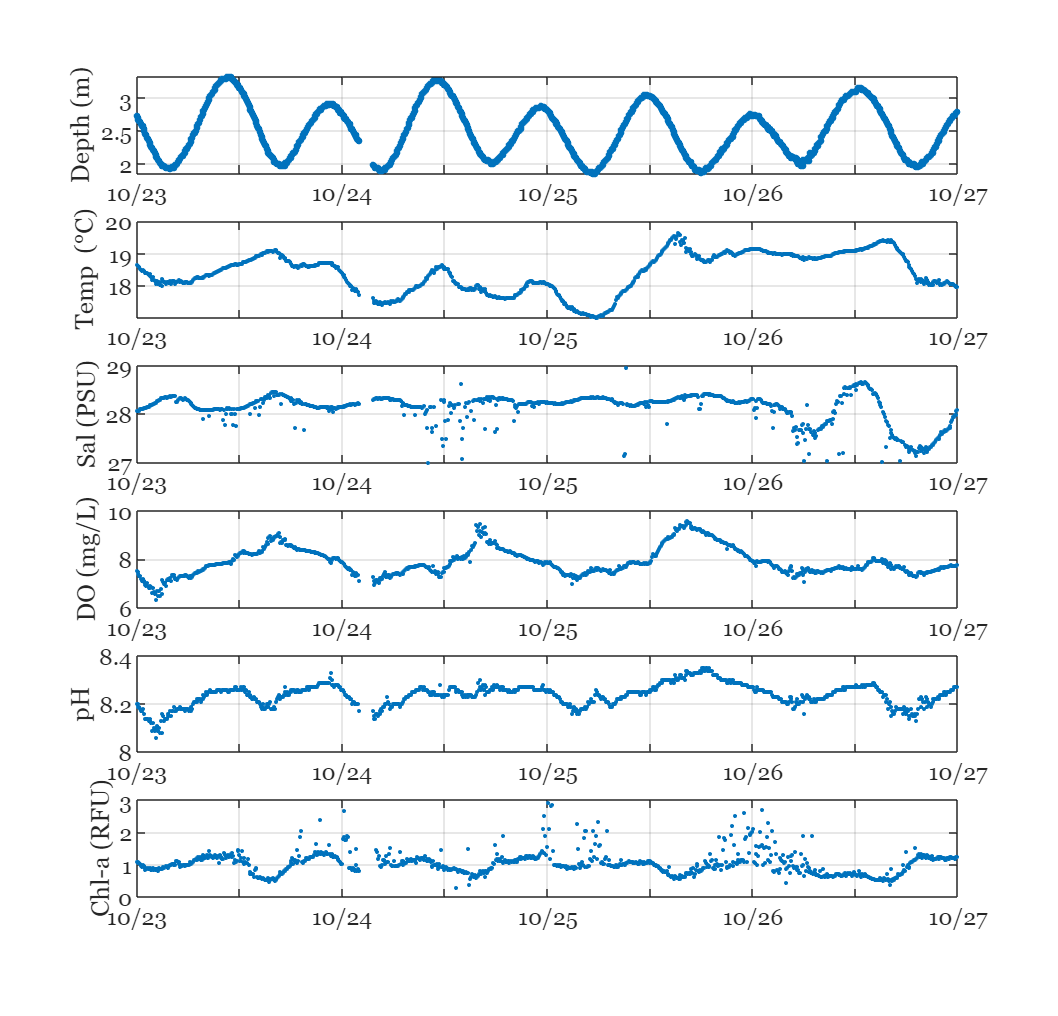


f = figure('DefaultAxesFontSize',14);
set(gca, 'FontName', 'Georgia');
f.Position = [0 0 1040 1000]; 

ax1 = subplot(6,1,1); % Breaks figure into plots (3 rows, 1 column, 1st plot)
plot(south.dn,south.Depth1_m,'.','MarkerSize',10) 
ylabel('Depth (m)','FontName','Georgia')  
xlim([datenum(2021,10,23,00,00,00) datenum(2021,10,27,00,00,00)])
% datetick('x','mm/dd','keeplimits')
grid on
set(ax1,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax2 = subplot(6,1,2); % Breaks figure into plots (3 rows, 1 column, 2nd plot)
plot(south.dn,south.Temp1_C,'.') 
ylabel('Temp (\circC)','FontName','Georgia')   
xlim([datenum(2021,10,23,00,00,00) datenum(2021,10,27,00,00,00)])
grid on
set(ax2,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax3 = subplot(6,1,3); % Breaks figure into plots (3 rows, 1 column, 2nd plot)
plot(south.dn,south.Salinity1_psu,'.') 
ylabel('Sal (PSU)','FontName','Georgia') 
xlim([datenum(2021,10,23,00,00,00) datenum(2021,10,27,00,00,00)])
ylim([27 29])
grid on
set(ax3,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax4 = subplot(6,1,4); % Breaks figure into plots (3 rows, 1 column, 2nd plot)
plot(south.dn,south.DO1_Conc_mgL,'.') 
ylabel('DO (mg/L)','FontName','Georgia') 
xlim([datenum(2021,10,23,00,00,00) datenum(2021,10,27,00,00,00)])
grid on
set(ax4,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax5 = subplot(6,1,5); % Breaks figure into plots (3 rows, 1 column, 2nd plot)
plot(south.dn,south.pH,'.') 
ylabel('pH','FontName','Georgia') 
xlim([datenum(2021,10,23,00,00,00) datenum(2021,10,27,00,00,00)])
grid on
set(ax5,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

% subplot(7,1,6) % Breaks figure into plots (3 rows, 1 column, 2nd plot)
% plot(south.dn,south.Turbidity_ntu,'.') 
% ylabel('Turbidity (NTU)') 
% xlim([datenum(2021,10,23,00,00,00) datenum(2021,10,27,00,00,00)])
% ylim([0 100])
% datetick('x','mm/dd','Keeplimits') 
% grid on

ax6 = subplot(6,1,6); % Breaks figure into plots (3 rows, 1 column, 2nd plot)
plot(south.dn,south.Chl_a_RFU,'.') 
ylabel('Chl-a (RFU)','FontName','Georgia') 
xlim([datenum(2021,10,23,00,00,00) datenum(2021,10,27,00,00,00)])
ylim([0 3])
grid on
set(ax6,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});